### **Carlos Cristóbal Rubio Hernández       A01745245**

# **Tarea 1**

# Mapa de Voronoi

#### 1. Construir mediante programación un mapa de Voronoi en un espacio de 256 x 256 pixeles.

clear all
close all
clc

Crear los puntos

prompt = "¿Cuántos pixeles tendrá el mapa? ";
tam=(input(prompt));
prompt = "¿Con cuantos puntos se formará el Mapa de Voronoi? ";
punt=(input(prompt));
puntos=randi(tam, [punt 2]);

Asigna nombre a los puntos

Crear matriz de 256x256

map= zeros(tam,tam,3);

Colores al azar

Color=randi(256,[punt 3]);

Compara las celdas de la matriz con los puntos

for i=1:tam
    for j=1:tam
        disi=sqrt(2*(tam^2))+100;
        for k=1:punt
            dis=sqrt((i-puntos(k,1))^2+(j-puntos(k,2))^2);
            if dis<disi
                ele=k;
                disi=dis;
                map(i,j,1)=Color(ele,1);
                map(i,j,2)=Color(ele,2);
                map(i,j,3)=Color(ele,3);
            end
        end
    end
end

Crear imagen

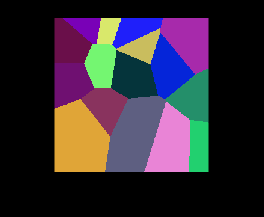

MapaDeVoronoi=figure('Name','Mapa de Voronoi','Color','black');
imshow(uint8(map));

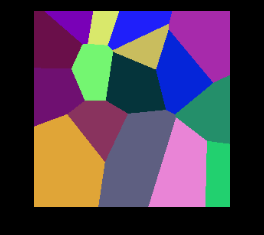

Escalado=figure('Name','Escalamiento','Color','black');
imshow(uint8(map),'InitialMagnification',10000,'Interpolation',"bilinear")